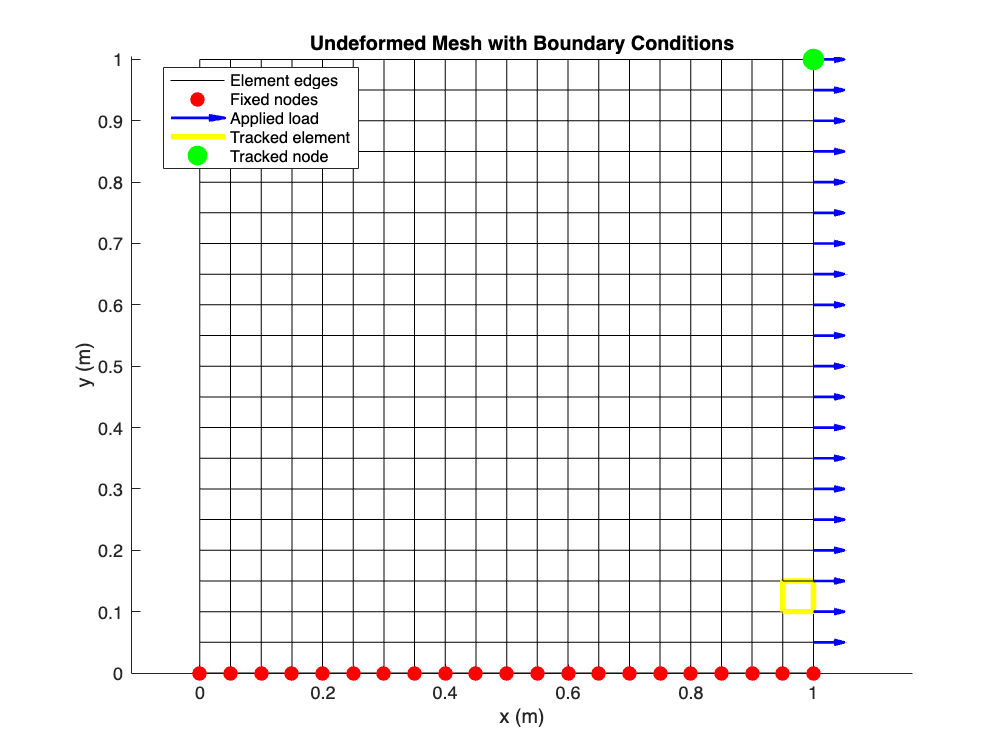

clear

% Parameters
L = 1;            % Domain length (square)
nx = 20;          % Number of elements in x
ny = 20;          % Number of elements in y
E = 200e3;        % Young's modulus (MPa)
ET=0.1*E;         % Hardening modulus (MPa)
nu = 0.3;         % Poisson's ratio
t = 0.01;         % Thickness (m)
sigma_y0=300;      % Initial yield stress (MPa)
beta=0;           % Kinematic-isotropic interpolation factor (1=isotropic)

% Derived
dx = L/nx;
dy = L/ny;
nnx = nx + 1;
nny = ny + 1;
nn = nnx * nny;   % Total number of nodes
nel = nx * ny;    % Number of elements
ndof = 2 * nn;    % Total DOFs

% Generate node coordinates
[X, Y] = meshgrid(0:dx:L, 0:dy:L);
nodes = [X(:), Y(:)];

% Generate element connectivity, with both elements and nodes indexed with
% adjacent ones in a column/the y direction
elements = zeros(nel, 4);
count = 1;
for i = 1:nx
    for j = 1:ny
        n1 = (i-1)*(ny+1) + j;
        n2 = n1 + ny + 1;
        n3 = n2 + 1;
        n4 = n1 + 1;
        elements(count, :) = [n1, n2, n3, n4];
        count = count + 1;
    end
end

% Tracking variables
tracked_node = (nx+1)*(ny+1);          % Node number to track (adjust as needed)
tracked_dof = 2*tracked_node; % e.g. 2*node = vertical displacement

tracked_element = 19*ny+3;  % Element number to track (adjust as needed)
tracked_gp = 4;             % Gauss point (1–4 for 2x2 integration)
figure; hold on; axis equal
title('Undeformed Mesh with Boundary Conditions')

% Preallocate handles for legend
h_elements = gobjects(1,1);
h_loads = gobjects(1,1);
h_tracked_elem = gobjects(1,1);

% Plot elements
for e = 1:nel
    coords_e = nodes(elements(e,:), :);
    coords_e = [coords_e; coords_e(1,:)]; % close the loop

    if e == tracked_element
        h_tracked_elem = plot(coords_e(:,1), coords_e(:,2), 'y-', 'LineWidth', 3);
    else
        h_elements = plot(coords_e(:,1), coords_e(:,2), 'k-');
    end
end

% Plot fixed supports (bottom edge)
fixed_nodes = find(abs(nodes(:,2)) < 1e-12);
fixed_dofs = reshape([2*fixed_nodes-1, 2*fixed_nodes]', [], 1);
free_dofs = setdiff(1:ndof, fixed_dofs);
h_fixed = plot(nodes(fixed_nodes,1), nodes(fixed_nodes,2), 'ro', 'MarkerFaceColor','r', 'LineWidth', 2);

% Plot applied loads (right edge)
right_nodes = find(abs(nodes(:,1) - L) < 1e-12 & abs(nodes(:,2)) > 1e-12);
arrow_scale = 0.05 * L;
for i = 1:length(right_nodes)
    x = nodes(right_nodes(i), 1);
    y = nodes(right_nodes(i), 2);
    h_loads = quiver(x, y, arrow_scale, 0, 0, 'b', 'LineWidth', 1.5, 'MaxHeadSize', 3);
end

% Highlight tracked node
tracked_node_coords = nodes(tracked_node, :);
h_tracked_node = plot(tracked_node_coords(1), tracked_node_coords(2), 'go', 'MarkerFaceColor','g', 'MarkerSize', 10, 'LineWidth', 2);

xlabel('x (m)'); ylabel('y (m)');

legend([h_elements, h_fixed, h_loads, h_tracked_elem, h_tracked_node], ...
       {'Element edges', 'Fixed nodes', 'Applied load', ...
        'Tracked element', 'Tracked node'}, ...
       'Location', 'best');

hold off
exportgraphics(gcf,"domain.png",Resolution=500)

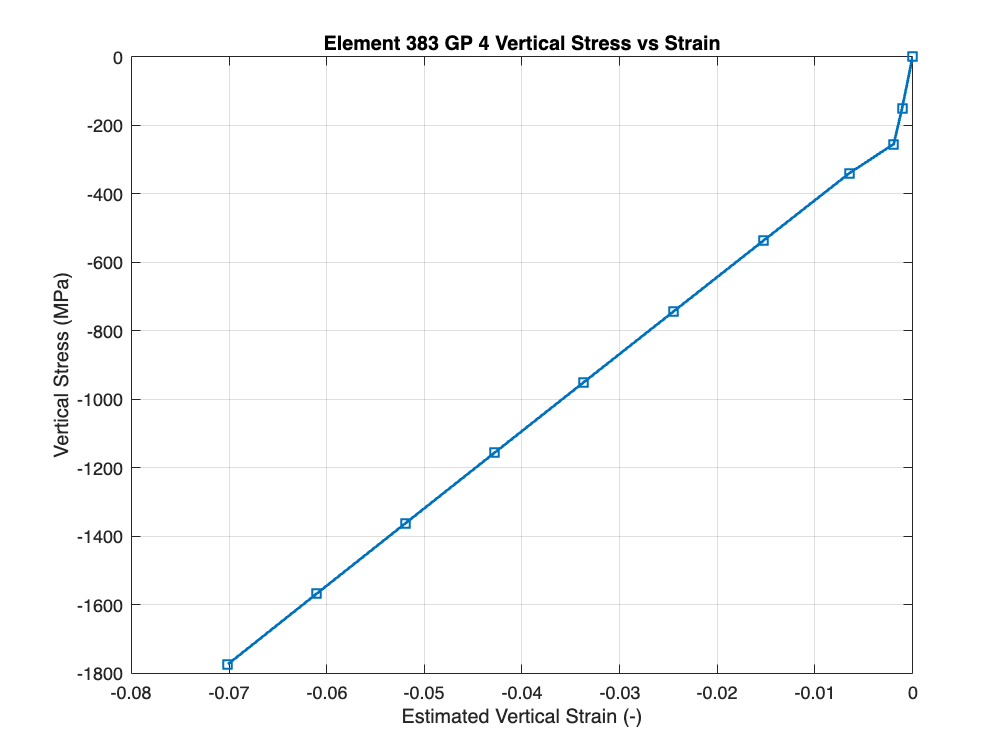


steps_per_level=10; % number of loading steps per loading cycle

% Apply loads (right edge nodes)
f_ext=zeros(ndof,1);
n_int=4*nel; % number of integration points
u=zeros(ndof,1);
dA=dx*t;

% initialize variables
[SIG,Ce,ALPHA,R,mu,H]=init(sigma_y0, E, ET, nu, n_int);
displacement_history = u(tracked_dof);
stress_history = SIG(2, 4*(tracked_element-1)+tracked_gp);
strain_history=(u(2*elements(tracked_element,3))-u(2*elements(tracked_element,4)))/dy;

yield_factor=2; % the approximate ratio between the final stresses and yield
load_per_node=yield_factor*sigma_y0*t*dx;

% apply the load incrementally
for i=1:steps_per_level
    f_ext(2*right_nodes-1) = load_per_node*i/steps_per_level;
    
    % Solve
    [u, SIG, ALPHA, R] = newton(SIG,u,Ce,ALPHA,R,mu,H,beta,f_ext,nodes,elements,t,nu,free_dofs);

    displacement_history(end+1)=u(tracked_dof);
    stress_history(end+1)=SIG(2, 4*(tracked_element-1)+tracked_gp);
    strain_history(end+1)=(u(2*elements(tracked_element,3))-u(2*elements(tracked_element,4)))/dy;
end

figure;
plot(strain_history, stress_history, 's-',LineWidth=1.5);
xlabel('Estimated Vertical Strain (-)');
ylabel('Vertical Stress (MPa)');
title(sprintf('Element %d GP %d Vertical Stress vs Strain', tracked_element, tracked_gp));
grid on;
exportgraphics(gcf,"histstrain.png",Resolution=500)

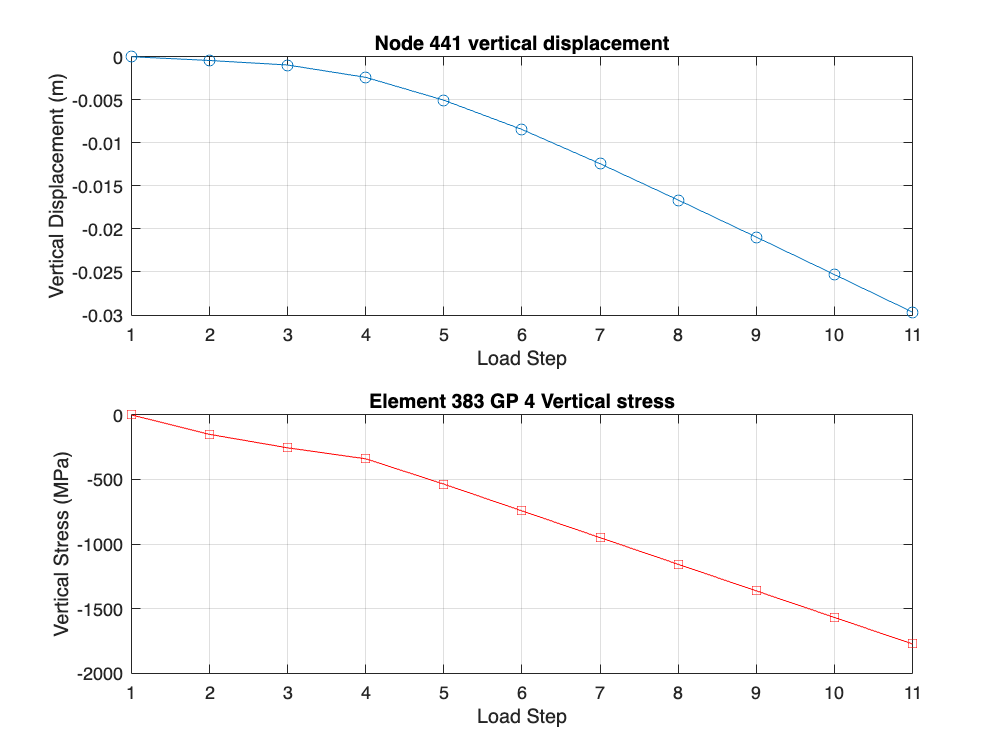


figure;
subplot(2,1,1);
plot(displacement_history, 'o-');
xlabel('Load Step');
ylabel('Vertical Displacement (m)');
title(sprintf('Node %d vertical displacement', tracked_node));
grid on;

subplot(2,1,2);
plot(stress_history, 's-r');
xlabel('Load Step');
ylabel('Vertical Stress (MPa)');
title(sprintf('Element %d GP %d Vertical stress', tracked_element, tracked_gp));
grid on;
exportgraphics(gcf,"histdispstress.png",Resolution=500)

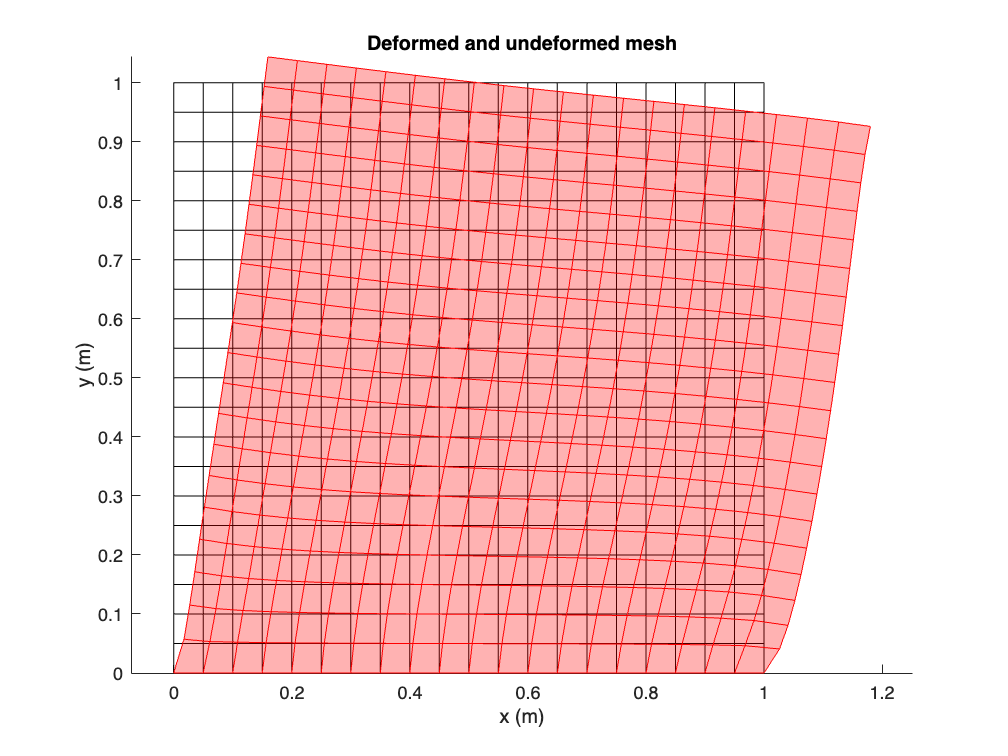


% Plot undeformed and deformed mesh
scale = 5e1 * dx; % scale factor for visualization

figure; hold on; axis equal
title('Deformed and undeformed mesh')
for e = 1:nel
    coords = nodes(elements(e,:), :);
    edof = reshape([2*elements(e,:)-1; 2*elements(e,:)], 1, []);
    
    fill(coords(:,1), coords(:,2), 'w', 'EdgeColor','k');
end
for e = 1:nel
    coords = nodes(elements(e,:), :);
    edof = reshape([2*elements(e,:)-1; 2*elements(e,:)], 1, []);
    u_elem = u(edof);
    coords_def = coords + reshape(u_elem, 2, [])'*scale;
    
    fill(coords_def(:,1), coords_def(:,2), 'r', 'FaceAlpha', 0.3, 'EdgeColor','r');
end
xlabel('x (m)'); ylabel('y (m)');
exportgraphics(gcf,"deformed.png",Resolution=500)